%导入数据
clear;clc
bankData=cell(3,2);
for i=1:3
    %读取对应年份数据
    year=int2str(2009+i);
    temp=readtable("商业银行指标数据.xls","Sheet",year,'VariableNamingRule','preserve');
    bankData{i,1}=year;
    bankData{i,2}=table2array(temp(:,2:end)); 
end
%银行名称列表
nameList=table2cell(temp(:,1));
%数据对应名称
variableTable={'固定资产净值' '经营费用'	'利息支出' '营业支出' '资产总计'	'员工人数' '利润总额' '投资收益' '存款' '贷款' '营业收入'};
year={'年份';'2010';'2011';'2012'};

for i=1:14
    temp1=zeros(3,11);
    for j=1:3
        temp2=bankData{j,2};
        temp1(j,:)=temp2(i,:);
    end
    A=temp1(:,5)';
    GM(A,nameList{i});
end

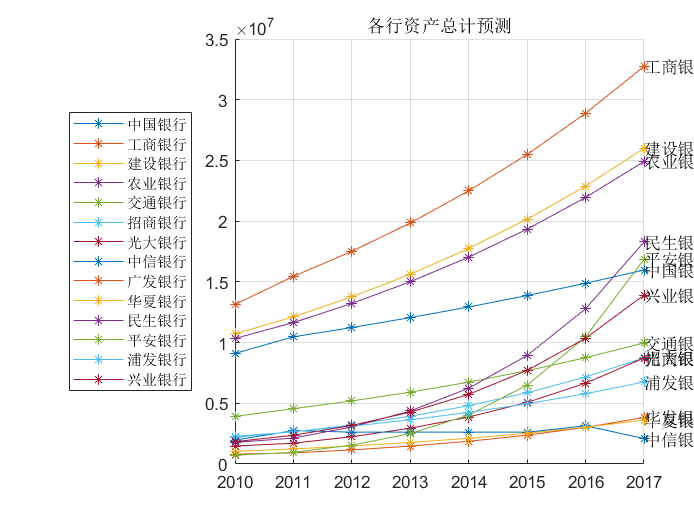

title('各行资产总计预测');
legend(nameList',"Location","westoutside");
set(gca,'xticklabel',{'2010','2011','2012','2013','2014','2015','2016','2017'});
grid on
hold off

function GM(A,bankName)
%GM(1,1)预测模型
syms a u;
c=[a,u]';%构成矩阵
Ago=cumsum(A);%原始数据一次累加,得到1-AGO序列xi(1)。
n=length(A);%原始数据个数
for k=1:(n-1)
    Z(k)=(Ago(k)+Ago(k+1))/2; %Z(i)为xi(1)的紧邻均值生成序列
end
Yn =A;%Yn为常数项向量
Yn(1)=[]; %从第二个数开始，即x(2),x(3)...
Yn=Yn';
E=[-Z;ones(1,n-1)]';%累加生成数据做均值
c=(E'*E)\(E'*Yn);%利用公式求出a，u
c= c';
a=c(1);%得到a的值
u=c(2);%得到u的值
F=[];
F(1)=A(1);
for k=2:(n+5)
    F(k)=(A(1)-u/a)/exp(a*(k-1))+u/a;%求出GM(1,1)模型公式
end
G=[];
G(1)=A(1);
for k=2:(n+5)
    %两者做差还原原序列，得到预测数据
    G(k)=F(k)-F(k-1);
end
t1=1:n;
t2=1:n+5;
%plot(t1,A,'bo--');
hold on
plot(t2,G,'*-'); 
text(n+5,G(n+5),bankName)
%title('预测结果');
%legend(bankName);
%后验差检验
e=A-G(1,length(A));
%相对误差
q=e/A;
s1=var(A);
s2=var(e);
%方差比
c=s2/s1;
len=length(e);
%小误差概率
p=0;  
for i=1:len
    if(abs(e(i))<0.6745*s1)
        p=p+1;
    end
end
p=p/len;
if (p>0.95) && (c<0.35)
    fprintf('好');
elseif (p>0.80) && (c<0.45)
    fprintf('合格');
elseif (p>0.70)&& (c<0.50)
    fprintf('勉强合格')
elseif (p<=0.70)&&(c>=0.65)
    fprintf('不合格')
end
fprintf('\n')
end